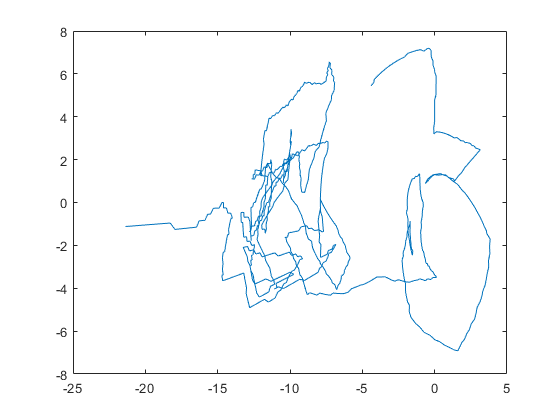

clearvars
data = readDFM17('C:\Users\Level1Zach\Desktop\HodographApp_Standalone\eclipseData\W8_L1_1100UTC_072220_ZASUS_Profile.txt');

u = -(data.Ws) .* sind(data.Wd); % from MetPy
v = -(data.Ws) .* cosd(data.Wd);
w = 17800; % min
t_l = find(data.Alt>=w,1,'first');
w = 27300; % max
t_u = find(data.Alt>=w,1,'first');
figure(3)
clf;
plot(u(t_l:t_u),v(t_l:t_u))

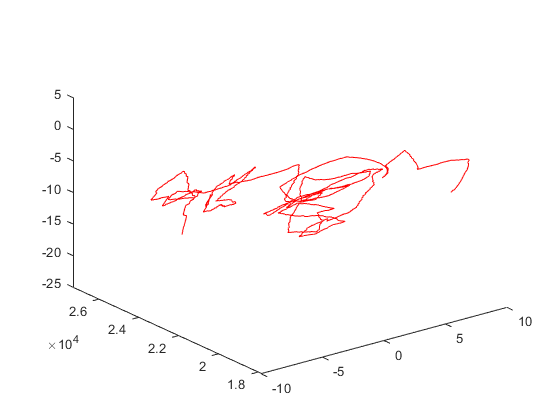

figure(2)
plot3(v(t_l:t_u),data.Alt(t_l:t_u),u(t_l:t_u),'r');

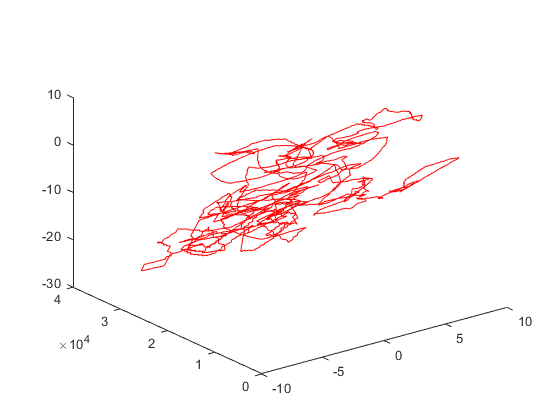


figure(4)
clf;
plot3(v,data.Alt,u,'r');

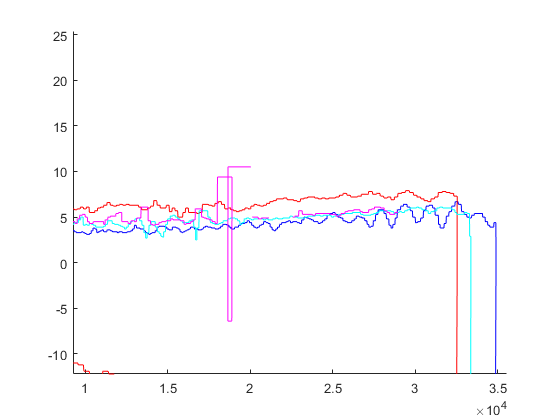


% 

% figure(8);
% clf;
% hold on
% plot(data.Alt,data.Rs,'b')
% 
% data2 = readDFM17('C:\Users\Level1Zach\Desktop\W6_L1_1700UTC_070820_ZASUS_profile.txt');
% 
% plot(data2.Alt,data2.Rs,'r')
% 
% data3 = readDFM17('C:\Users\Level1Zach\Desktop\W7_L1_0500UTC_071620_Ace_Profile.txt');
% 
% plot(data3.Alt,data3.Rs,'c')
% 
% data4 = readDFM17('C:\Users\Level1Zach\Desktop\W4_L1_1730UTC_062420_Oval_CLARA_Profile.txt');
% 
% plot(data4.Alt,data4.Rs,'m')
% xlim([9266 35562])
% ylim([-12.2 25.4])


 
y=70

y = 70